Problem A1 & A2

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts.Sheet = "Tesla";
opts.DataRange = "A2:G266";

% Specify column names and types
opts.VariableNames = ["Date", "Open", "High", "Low", "Close", "AdjClose", "Volume"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

% Import the data
Tesla = readtimetable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts, "UseExcel", false, "RowTimes", "Date");

% Clear temporary variables
clear opts

% Display results
Tesla

Tesla = 265×6 timetable
       Date         Open      High      Low      Close     AdjClose      Volume  
    ___________    ______    ______    ______    ______    ________    __________

    03-Oct-2022     254.5    255.16    241.01     242.4      242.4     9.8364e+07
    04-Oct-2022    250.52     257.5    242.01    249.44     249.44     1.0958e+08
    05-Oct-2022    245.01    246.67    233.27    240.81     240.81     8.6983e+07
    06-Oct-2022    239.44    244.58    235.35    238.13     238.13     6.9298e+07
    07-Oct-2022    233.94    234.57    222.02    223.07     223.07     8.3917e+07
    10-Oct-2022    223.93    226.99    218.36    222.96     2

%Calculate Descriptive Statistics [Using Adj Close]
Cl_P = Tesla.AdjClose;
Op_P = Tesla.Open;

%Calculate Numerator
Price_Diff = Cl_P-Op_P;

%Element-Wise Division
Tesla_Returns = Price_Diff./Op_P

Tesla_Returns =    -0.0475
   -0.0043
   -0.0171
   -0.0055
   -0.0465
   -0.0043
   -0.0201
    0.0089
    0.0644
   -0.0849



%Mean
Tes_Mean = mean(Tesla_Returns)

Tes_Mean = 3.6521e-04


%Variance
Std_Tes = std(Tesla_Returns)

Std_Tes = 0.0318

Var_Tes = Std_Tes*Std_Tes

Var_Tes = 0.0010


%Skew
Skew_Tes = skewness(Tesla_Returns)

Skew_Tes = 0.0171


%Kurtosis
Tes_Kurt = kurtosis(Tesla_Returns)

Tes_Kurt = 3.4079


%Moving Average
MovingA_Tesla = movmean(Tesla.AdjClose,20);


Tesla Analysis: Note: These figures are non-annualized and are calculated using the daily returns for each stock. Tesla has a relatively high daily volatility at about 3.18%. In annual terms, the standard deviation given by the formula: .0318 * sqrt(252) would produce annual volatility of 50.48% which is high but expected for a volatile stock like Tesla. Likewise, the kurtosis is higher than 3 which is  the expected kurtosis for a normal distribution. With fatter tails, Tesla has a higher probability of extreme positive or negative returns. For an investor who is less risk-averse, they may see the higher kurtosis and positive skew as a profitable investment. However, another more risk-averse investor may see the high volatility as not worth the given level of returns. 

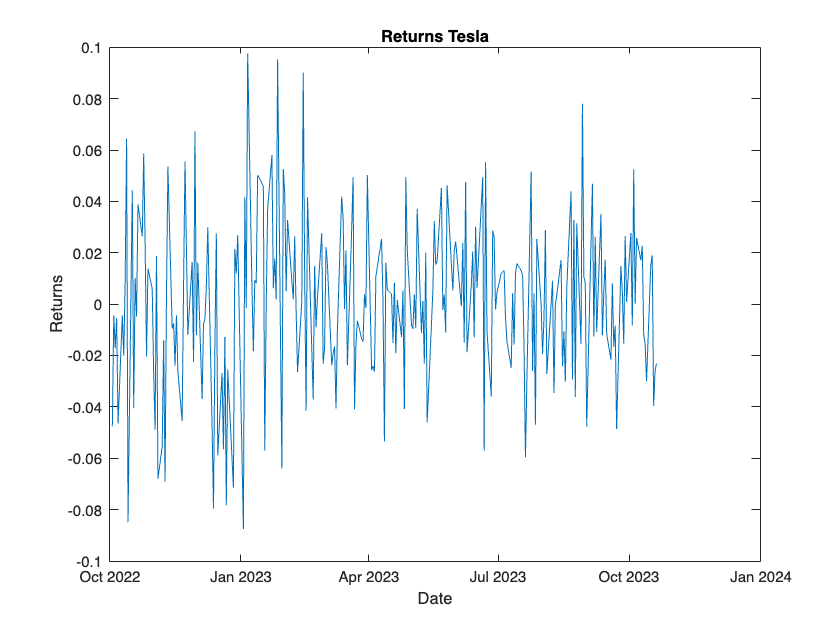


%Plot Returns & Moving Average
%We have to drop the first 20 instances of the dataset as they are not averaged according to the 20-day window 
Moving_Tesla = MovingA_Tesla(19:265,1);
figure;
plot(Tesla.Date, MovingA_Tesla)
title ("Moving Average Tesla")
xlabel("Date")
ylabel("Price")
hold off;

figure;
plot(Tesla.Date, Tesla_Returns)
title("Returns Tesla")
xlabel("Date")
ylabel("Returns")
hold off;

% Set up the Import Options and import the data
opts2 = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts2.Sheet = "Airbnb";
opts2.DataRange = "A2:G266";

% Specify column names and types
opts2.VariableNames = ["Date", "Open", "High", "Low", "Close", "AdjClose", "Volume"];
opts2.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

% Import the data
Airbnb = readtimetable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts2, "UseExcel", false, "RowTimes", "Date");

% Clear temporary variables
clear opts2

% Display results
Airbnb

Airbnb = 265×6 timetable
       Date         Open      High      Low      Close     AdjClose      Volume  
    ___________    ______    ______    ______    ______    ________    __________

    03-Oct-2022    105.49    106.35    102.18       105        105     6.2089e+06
    04-Oct-2022    109.14    111.61    108.68    110.81     110.81      4.835e+06
    05-Oct-2022    110.52    112.34    107.84    111.76     111.76     4.0087e+06
    06-Oct-2022       112    114.41     110.2    111.58     111.58     3.4465e+06
    07-Oct-2022    108.87    109.53     107.1    108.54     108.54     3.3527e+06
    10-Oct-2022    108.55    111.62    107.41    110.99     


%Calculate Descriptive Statistics [Using Adj Close]
Cl_P_Airbnb = Airbnb.AdjClose

Cl_P_Airbnb =   105.0000
  110.8100
  111.7600
  111.5800
  108.5400
  110.9900
  106.8200
  112.3500
  112.6500
  109.1600


Op_P_Airbnb = Airbnb.Open

Op_P_Airbnb =   105.4900
  109.1400
  110.5200
  112.0000
  108.8700
  108.5500
  110.9880
  107.4700
  107.3000
  115.0000



%Calculate Numerator
Price_Diff_A = Cl_P_Airbnb-Op_P_Airbnb 

Price_Diff_A =    -0.4900
    1.6700
    1.2400
   -0.4200
   -0.3300
    2.4400
   -4.1680
    4.8800
    5.3500
   -5.8400


%Element-Wise Division
Airbnb_Returns = Price_Diff_A./Op_P

Airbnb_Returns =    -0.0019
    0.0067
    0.0051
   -0.0018
   -0.0014
    0.0109
   -0.0189
    0.0227
    0.0257
   -0.0261


%Mean
Airbnb_Mean = mean(Airbnb_Returns)

Airbnb_Mean = 0.0012

%Calculate Std.Dev 
Std_Airbnb_Returns =std(Airbnb_Returns)

Std_Airbnb_Returns = 0.0138

%Variance
Var_Airbnb = Std_Airbnb_Returns * Std_Airbnb_Returns

Var_Airbnb = 1.9092e-04

%Skew
Skew_Air = skewness(Airbnb_Returns)

Skew_Air = 0.1966

%Kurtosis
Air_Kurt = kurtosis(Airbnb_Returns)

Air_Kurt = 3.5156


%Import Market Portfolio 
%Since Tesla & Airbnb are within the NASDAQ Composite, NASDAQ is used as
%the overall market portfolio. A portfolio contaning nearly all equity
%assets in the Universe that are value weighted according to the market cap. 


Airbnb: Airbnb has an annualized effective return of 35.28% and an annualized standard deviation of 21.9%. Its sharpe ratio is 1.39 which is a good sharpe ratio. It also has a high kurtosis indicating extreme outcomes at the end of its distribution and a positive skew. Relatively speaking, Airbnb seems like a more reasonable investment compared to Tesla.

% Set up the Import Options and import the data
opts7 = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts7.Sheet = "Market Portfolio Nasdaq";
opts7.DataRange = "A2:G266";

% Specify column names and types
opts7.VariableNames = ["Date", "Open", "High", "Low", "Close", "AdjClose", "Volume"];
opts7.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

% Import the data
Mktd = readtimetable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts7, "UseExcel", false, "RowTimes", "Date");

% Clear temporary variables
clear opts7

% Display results
Mktd

Mktd = 265×6 timetable
       Date        Open     High      Low     Close    AdjClose      Volume  
    ___________    _____    _____    _____    _____    ________    __________

    03-Oct-2022    10659    10875    10578    10815     10815      4.4154e+09
    04-Oct-2022    11055    11190    11044    11176     11176      5.0048e+09
    05-Oct-2022    11023    11210    10911    11149     11149      4.0919e+09
    06-Oct-2022    11129    11230    11051    11073     11073      4.4233e+09
    07-Oct-2022    10877    10892    10609    10652     10652      4.6342e+09
    10-Oct-2022    10660    10670    10449    10542     10542      3.9896e+09
    

%Returns
Mktd_Returns = (Mktd.AdjClose - Mktd.Open)./Mktd.Open

Mktd_Returns =     0.0147
    0.0110
    0.0114
   -0.0050
   -0.0207
   -0.0111
   -0.0055
   -0.0019
    0.0511
   -0.0392



%Mean
Mkt_Mean = mean(Mktd_Returns)

Mkt_Mean = 6.8004e-04


%St Dev & Variance
Mkt_Std = std(Mktd_Returns)

Mkt_Std = 0.0117

Mkt_Var = Mkt_Std*Mkt_Std

Mkt_Var = 1.3678e-04


%Skew
Skew_Mkt = skewness(Mktd_Returns)

Skew_Mkt = 0.2495


%Kurtosis
Kurt_Mkt = kurtosis(Mktd_Returns)

Kurt_Mkt = 4.5741


%Moving Average (20-Day Window)
MovingA_Air = movmean(Cl_P_Airbnb,20)

MovingA_Air =   109.9660
  110.5600
  111.1750
  111.6131
  111.9979
  112.5280
  112.7694
  113.1035
  113.2261
  113.1647


%Drop the first 20 instances
MovingA_Air = MovingA_Air(19:265,1)

MovingA_Air =   108.8060
  108.2935
  108.3140
  107.7470
  107.2005
  106.5785
  105.6935
  104.5845
  103.5505
  102.3920


Airbnb_Date = Airbnb.Date(19:265)

Airbnb_Date = 247×1 datetime array
   27-Oct-2022
   28-Oct-2022
   31-Oct-2022
   01-Nov-2022
   02-Nov-2022
   03-Nov-2022
   04-Nov-2022
   07-Nov-2022
   08-Nov-2022
   09-Nov-2022
   10-Nov-2022
   11-Nov-2022
   14-Nov-2022
   15-Nov-2022
   16-Nov-2022
   17-Nov-2022
   18-Nov-2022
   21-Nov-2022
   22-Nov-2022
   23-Nov-2022
   25-Nov-2022
   28-Nov-2022
   29-Nov-2022
   30-Nov-2022
   01-Dec-2022
   02-Dec-2022
   05-Dec-2022
   06-Dec-2022
   07-Dec-2022
   08-Dec-2022


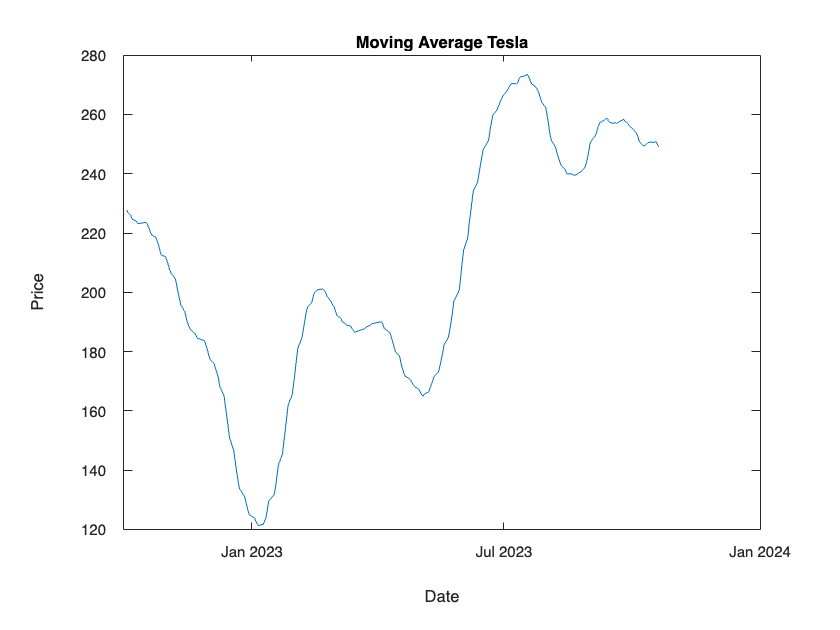


%Plot Returns & Moving Average
figure;
plot(Airbnb_Date, MovingA_Air)
title("Moving Average Airbnb")
xlabel("Dates")
ylabel("Price")
hold off; 

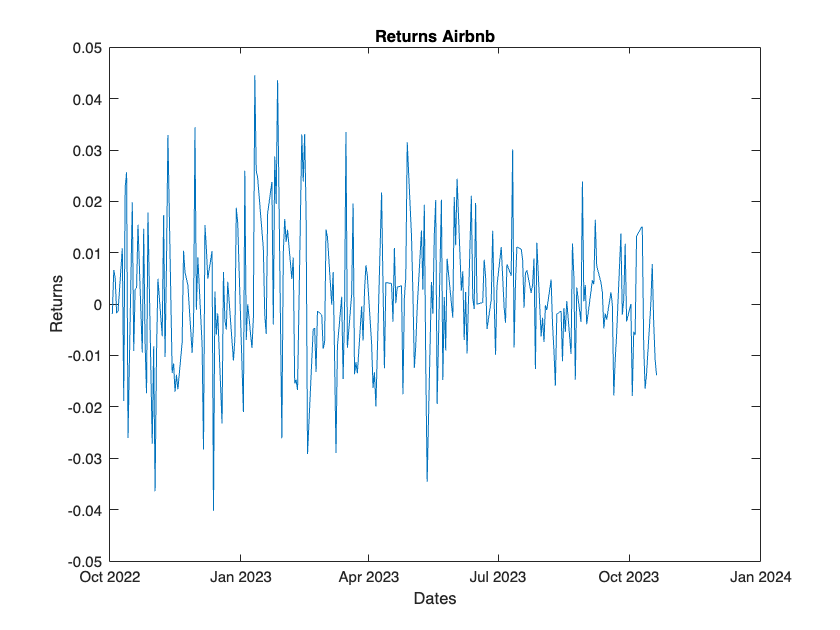


figure;
plot(Airbnb.Date, Airbnb_Returns)
title("Returns Airbnb")
xlabel("Dates")
ylabel("Returns")
hold off;

Airbnb Returns fluctuated more on a daily basis in early January, however its volatility seems to have decreased recently. The moving average shows a generally increasing line with a small dip in January of this year, similar to the moving average of Tesla's. It seems that these two stocks-- given that they are both tech stocks-- seem to respond similarly to systematic risk in the market, and given their high betas that would intuitively make sense. The dip in January can be attributed to interest rate hikes by the Federal Reserve and the earning reports of big tech corporations. A possible trading strategy that can be learned from here is to  sell off when the Federal Reserve is hawkiwsh and when the posibility of an interest rate hike is known with some certainty and buy after its effect has rippled through the market.

Problem A3

%Need data type array to create Histogram 
%Import

% Set up the Import Options and import the data
opts4 = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts4.Sheet = "Airbnb";
opts4.DataRange = "A2:G266";

% Specify column names and types
opts4.VariableNames = ["Date", "Open", "High", "Low", "Close", "AdjClose", "Volume"];
opts4.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Import the data
Airbnb_Array = readtable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts4, "UseExcel", false);

% Convert to output type
Airbnb_Array = table2array(Airbnb_Array);

% Clear temporary variables
clear opts4

% Display results
Airbnb_Array

Airbnb_Array = 1.0e+07 *

    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.6209
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.4835
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.4009
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.3447
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.3353
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.3945
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.5697
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.5547
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.6172
    0.0045    0.0000    0.0000    0.0000    0.0000    0.0000    0.5002


% Set up the Import Options and import the data
opts5 = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts5.Sheet = "Tesla";
opts5.DataRange = "A2:G266";

% Specify column names and types
opts5.VariableNames = ["Date", "Open", "High", "Low", "Close", "AdjClose", "Volume"];
opts5.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Import the data
Tesla_Array = readtable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts5, "UseExcel", false);

% Convert to output type
Tesla_Array = table2array(Tesla_Array);

% Clear temporary variables
clear opts5

% Display results
Tesla_Array

Tesla_Array = 1.0e+08 *

    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.9836
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    1.0958
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.8698
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.6930
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.8392
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.6793
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.7701
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.6686
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.9148
    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.9412



%Indexing to obtain array columns
AdjClose_Array_Air = Airbnb_Array(:, 6)

AdjClose_Array_Air =   105.0000
  110.8100
  111.7600
  111.5800
  108.5400
  110.9900
  106.8200
  112.3500
  112.6500
  109.1600


Open_Air = Airbnb_Array(:,2)

Open_Air =   105.4900
  109.1400
  110.5200
  112.0000
  108.8700
  108.5500
  110.9880
  107.4700
  107.3000
  115.0000


AdjClose_Array_Tes = Tesla_Array(:,6)

AdjClose_Array_Tes =   242.4000
  249.4400
  240.8100
  238.1300
  223.0700
  222.9600
  216.5000
  217.2400
  221.7200
  204.9900


Open_Tes = Tesla_Array(:,2)

Open_Tes =   254.5000
  250.5200
  245.0100
  239.4400
  233.9400
  223.9300
  220.9500
  215.3300
  208.3000
  224.0100



%Calculate return using Array class-type
Price_Diff_Air_Array =AdjClose_Array_Air - Open_Air

Price_Diff_Air_Array =    -0.4900
    1.6700
    1.2400
   -0.4200
   -0.3300
    2.4400
   -4.1680
    4.8800
    5.3500
   -5.8400


return_array_air = Price_Diff_Air_Array./Open_Air 

return_array_air =    -0.0046
    0.0153
    0.0112
   -0.0037
   -0.0030
    0.0225
   -0.0376
    0.0454
    0.0499
   -0.0508


Price_Diff_Tes_Array = AdjClose_Array_Tes - Open_Tes

Price_Diff_Tes_Array =   -12.1000
   -1.0800
   -4.2000
   -1.3100
  -10.8700
   -0.9700
   -4.4500
    1.9100
   13.4200
  -19.0200


return_array_tes = Price_Diff_Tes_Array./Open_Tes

return_array_tes =    -0.0475
   -0.0043
   -0.0171
   -0.0055
   -0.0465
   -0.0043
   -0.0201
    0.0089
    0.0644
   -0.0849


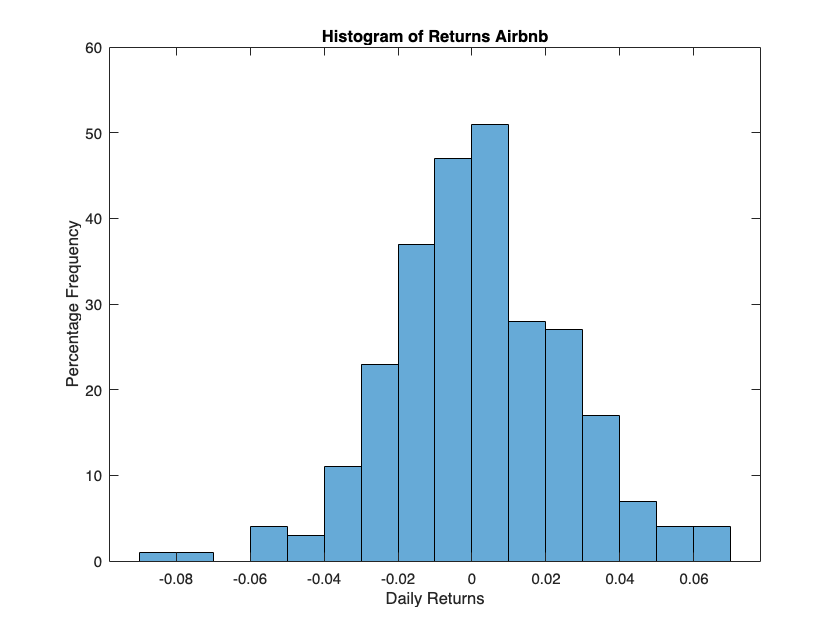


%Plot Histogram
figure;
histogram(return_array_air)
title("Histogram of Returns Airbnb")
xlabel("Daily Returns")
ylabel("Percentage Frequency")
hold off;

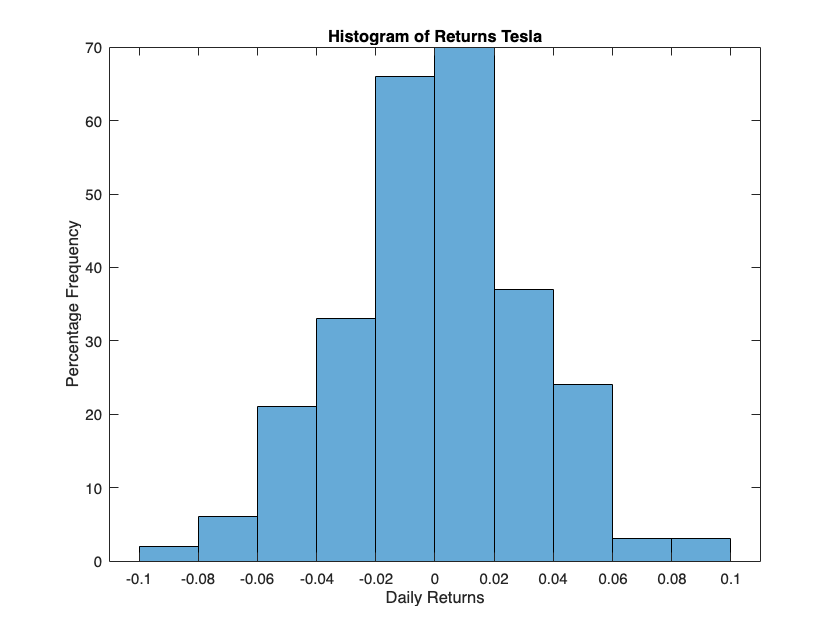


figure;
histogram(return_array_tes)
title("Histogram of Returns Tesla")
xlabel("Daily Returns")
ylabel("Percentage Frequency")
hold off;

%Plot Kernal Density 
figure;
[f,xi] = ksdensity(return_array_tes)

f =     0.0026    0.0055    0.0110    0.0207    0.0370    0.0625    0.1001    0.1520    0.2194    0.3019    0.3968    0.5002    0.6074    0.7142    0.8183    0.9202    1.0229    1.1319    1.2538    1.3949    1.5602    1.7525    1.9717    2.2146    2.4756    2.7475    3.0229    3.2968    3.5690    3.8470    4.1463    4.4898    4.9033    5.4095    6.0206    6.7335    7.5281    8.3696    9.2148   10.0194   10.7457   11.3688   11.8794   12.2825   12.5932   12.8282   12.9984   13.1037   13.1325   13.0668


xi =    -0.1174   -0.1150   -0.1125   -0.1100   -0.1075   -0.1051   -0.1026   -0.1001   -0.0976   -0.0952   -0.0927   -0.0902   -0.0877   -0.0853   -0.0828   -0.0803   -0.0778   -0.0754   -0.0729   -0.0704   -0.0679   -0.0655   -0.0630   -0.0605   -0.0580   -0.0556   -0.0531   -0.0506   -0.0481   -0.0457   -0.0432   -0.0407   -0.0382   -0.0358   -0.0333   -0.0308   -0.0283   -0.0259   -0.0234   -0.0209   -0.0184   -0.0160   -0.0135   -0.0110   -0.0085   -0.0061   -0.0036   -0.0011    0.0014    0.0038


title("Kernal Density Plot Tesla")
xlabel("Returns")
ylabel("Density")
c = plot (xi, f)

c =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.1174 -0.1150 -0.1125 -0.1100 -0.1075 -0.1051 -0.1026 -0.1001 -0.0976 -0.0952 -0.0927 -0.0902 -0.0877 -0.0853 -0.0828 -0.0803 -0.0778 -0.0754 -0.0729 -0.0704 -0.0679 -0.0655 -0.0630 -0.0605 -0.0580 -0.0556 … ] (1×100 double)
              YData: [0.0026 0.0055 0.0110 0.0207 0.0370 0.0625 0.1001 0.1520 0.2194 0.3019 0.3968 0.5002 0.6074 0.7142 0.8183 0.9202 1.0229 1.1319 1.2538 1.3949 1.5602 1.7525 1.9717 2.2146 2.4756 2.7475 3.0229 3.2968 3.5690 3.8470 … ] (1×100 double)

  Show <a href="matlab:if exist('c', 'var'), matlab.graphics.internal.getForDisplay('c', c, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('c'), end">all properties</a

hold off 

figure;
[f,xi] = ksdensity(return_array_air)

f =     0.0022    0.0045    0.0086    0.0157    0.0270    0.0436    0.0664    0.0958    0.1306    0.1691    0.2085    0.2455    0.2774    0.3025    0.3202    0.3316    0.3398    0.3493    0.3659    0.3962    0.4458    0.5177    0.6116    0.7233    0.8467    0.9761    1.1093    1.2502    1.4085    1.5990    1.8383    2.1423    2.5243    2.9938    3.5560    4.2118    4.9580    5.7861    6.6830    7.6308    8.6077    9.5903   10.5566   11.4892   12.3778   13.2203   14.0203   14.7824   15.5059   16.1797


xi =    -0.1036   -0.1016   -0.0997   -0.0977   -0.0958   -0.0939   -0.0919   -0.0900   -0.0880   -0.0861   -0.0841   -0.0822   -0.0802   -0.0783   -0.0764   -0.0744   -0.0725   -0.0705   -0.0686   -0.0666   -0.0647   -0.0628   -0.0608   -0.0589   -0.0569   -0.0550   -0.0530   -0.0511   -0.0491   -0.0472   -0.0453   -0.0433   -0.0414   -0.0394   -0.0375   -0.0355   -0.0336   -0.0317   -0.0297   -0.0278   -0.0258   -0.0239   -0.0219   -0.0200   -0.0180   -0.0161   -0.0142   -0.0122   -0.0103   -0.0083


title("Kernal Density Plot Airbnb")
xlabel("Returns")
ylabel("Density")
hold on 
figure 
d = plot (xi, f)

d =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.1036 -0.1016 -0.0997 -0.0977 -0.0958 -0.0939 -0.0919 -0.0900 -0.0880 -0.0861 -0.0841 -0.0822 -0.0802 -0.0783 -0.0764 -0.0744 -0.0725 -0.0705 -0.0686 -0.0666 -0.0647 -0.0628 -0.0608 -0.0589 -0.0569 -0.0550 … ] (1×100 double)
              YData: [0.0022 0.0045 0.0086 0.0157 0.0270 0.0436 0.0664 0.0958 0.1306 0.1691 0.2085 0.2455 0.2774 0.3025 0.3202 0.3316 0.3398 0.3493 0.3659 0.3962 0.4458 0.5177 0.6116 0.7233 0.8467 0.9761 1.1093 1.2502 1.4085 1.5990 … ] (1×100 double)

  Show <a href="matlab:if exist('d', 'var'), matlab.graphics.internal.getForDisplay('d', d, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('d'), end">all properties</a

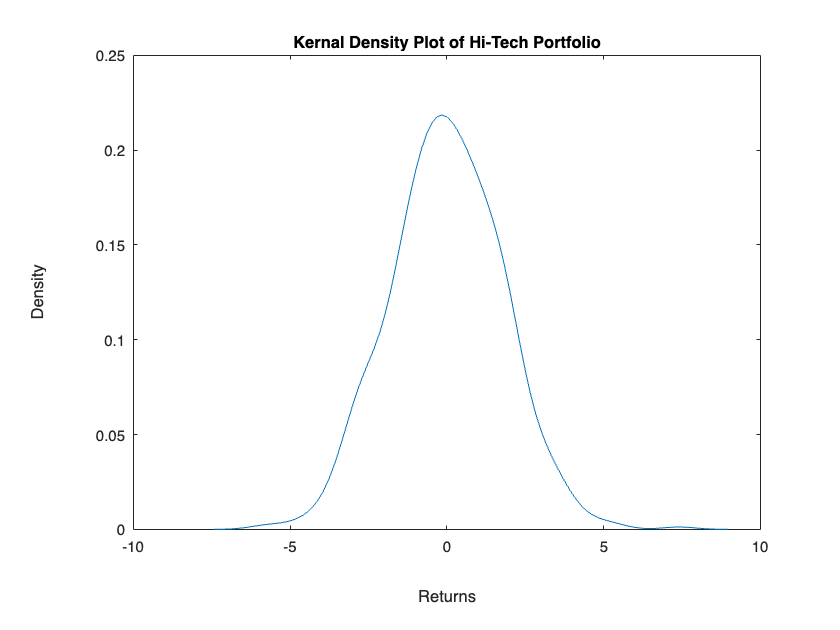

hold off 

For Tesla the plotted returns show a decrease in volatility throughout the year similarly to Airbnb. The x-axis of the kernal density plot show the returns and the y-axis show the frequency of that x-axis return occuring. 

Problem A4

% Set up the Import Options and import the data
opts6 = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet and range
opts6.Sheet = "Treasury Bill Rate";
opts6.DataRange = "A2:G266";

% Specify column names and types
opts6.VariableNames = ["Date", "Open", "High", "Low", "Close", "AdjClose", "Volume"];
opts6.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double"];

% Import the data
Rf = readtimetable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts6, "UseExcel", false, "RowTimes", "Date");

% Clear temporary variables
clear opts6

% Display results
Rf

Rf = 265×6 timetable
       Date        Open     High      Low     Close    AdjClose    Volume
    ___________    _____    _____    _____    _____    ________    ______

    03-Oct-2022    3.165     3.19     3.14     3.15      3.15        0   
    04-Oct-2022    3.305     3.32     3.26    3.315     3.315        0   
    05-Oct-2022     3.29    3.315     3.29    3.293     3.293        0   
    06-Oct-2022    3.285    3.298    3.263    3.288     3.288        0   
    07-Oct-2022    3.273    3.295    3.233    3.293     3.293        0   
    10-Oct-2022    3.285    3.285    3.285    3.285     3.285        0   
    11-Oct-2022    3.293     


%Average risk-free rate yield
Rf_Mean= mean(Rf.AdjClose)

Rf_Mean = 4.7568

risk_free_rate= Rf_Mean/100

risk_free_rate = 0.0476


%Calculate Beta
%Obtain the covariance-variance matrix for both stocks with market
Covar_Tes = cov(return_array_tes,Mktd_Returns)

Covar_Tes =     0.0010    0.0002
    0.0002    0.0001



%The off-diagonal is the covariance with market
Mkt_Tes_Covar = Covar_Tes(1,2) 

Mkt_Tes_Covar = 2.4428e-04

Covar_Airbnb = cov(return_array_air, Mktd_Returns)

Covar_Airbnb = 1.0e-03 *

    0.5637    0.1829
    0.1829    0.1368


Mkt_Air_Covar = Covar_Airbnb(1,2)

Mkt_Air_Covar = 1.8291e-04


%Calculate daily beta
Var_Mkt = Covar_Airbnb(2,2)

Var_Mkt = 1.3678e-04

Beta_Tes = Mkt_Tes_Covar/Var_Mkt

Beta_Tes = 1.7860

Beta_Air = Mkt_Air_Covar/Var_Mkt

Beta_Air = 1.3373


%Daily Returns Using CAPM
Tes_CAPM_Returns = risk_free_rate + Beta_Tes*(Mkt_Mean - risk_free_rate)

Tes_CAPM_Returns = -0.0362

Air_CAPM_Returns = risk_free_rate + Beta_Air*(Mkt_Mean - risk_free_rate)

Air_CAPM_Returns = -0.0151

Problem B1

% Set up the Import Options and import the data
opts9 = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts9.Sheet = "Fama French Factor";
opts9.DataRange = "A2:E629";

% Specify column names and types
opts9.VariableNames = ["Date", "Mkt_RF", "SMB", "HML", "RF"];
opts9.VariableTypes = ["double", "double", "double", "double", "double"];

% Import the data
Factor = readtable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts9, "UseExcel", false);

% Clear temporary variables
clear opts9

% Display results
Factor

Factor = 628×5 table
      Date       Mkt_RF     SMB      HML     RF
    _________    ______    _____    _____    __

    2.021e+07     1.73      0.93    -1.47    0 
    2.021e+07     1.48     -0.85    -1.08    0 
    2.021e+07     0.15      0.43      0.7    0 
    2.021e+07     1.23      0.38     0.37    0 
    2.021e+07     0.58      1.07    -0.48    0 
    2.021e+07     0.96      2.11     0.39    0 
    2.021e+07     0.05      0.71    -0.17    0 
    2.021e+07    -0.08     -0.49     0.61    0 
    2.021e+07     0.19     -0.22    -0.43    0 
    2.021e+07     0.49     -0.14     0.49    0 
    2.021e+07    -0.14     -0.61     1.89    0 
    2.021e+07    -0.21     -0.85     0.61    0 
    2.021e+07    -0.63     -1.55     -0.2    0 
    2.021e+07     0.16      1.79     0.72    0 
    2.021e+07    -1.13     -0.05     3.1

% Set up the Import Options and import the data
opts8 = spreadsheetImportOptions("NumVariables", 6);

% Specify sheet and range
opts8.Sheet = "2 Industry Portfolio";
opts8.DataRange = "A2:F629";

% Specify column names and types
opts8.VariableNames = ["Date", "Cnsmr", "Manuf", "HiTec", "Hlth_", "Other"];
opts8.VariableTypes = ["double", "double", "double", "double", "double", "double"];

% Import the data
Port = readtable("/Users/jasonting/Desktop/Math Finance HW 2.xlsx", opts8, "UseExcel", false);

% Clear temporary variables
clear opts8

% Display results
Port

Port = 628×6 table
      Date       Cnsmr    Manuf    HiTec    Hlth_    Other
    _________    _____    _____    _____    _____    _____

    2.021e+07     1.45     2.42     2.69     2.85     2.23
    2.021e+07     0.53     1.48     1.82     2.73     1.45
    2.021e+07     1.94     2.25     0.66     2.17     0.67
    2.021e+07     2.04     1.14        2      2.6     2.16
    2.021e+07     1.03     1.07     1.78     1.81      0.9
    2.021e+07     2.38     3.25     3.03     5.81     2.44
    2.021e+07      0.9     0.63     1.48     1.41     0.78
    2.021e+07    -0.01      0.9    -0.35    -0.03     0.07
    2.021e+07     0.03    -0.57     0.69    -0.87    -0.02
    2.021e+07     0.26     0.94     0.94     0.06      0.4
    2.021e+07     0.02     1.58     1.34     0.34     0.66
    2.021

%Calculate Portfolio Descriptive Statistics
Port_Mean_H = mean(Port.HiTec)

Port_Mean_H = -0.0048

Port_Var_H = var(Port.HiTec)

Port_Var_H = 3.1673

Port_Std_H = std(Port.HiTec)

Port_Std_H = 1.7797

Port_Skew_H = skewness(Port.HiTec)

Port_Skew_H = 0.0559

Port_Kurt_H = kurtosis(Port.HiTec)

Port_Kurt_H = 3.3243


Port_Mean_Hl = mean(Port.Hlth_)

Port_Mean_Hl = -0.0836

Port_Var_Hl = var(Port.Hlth_)

Port_Var_Hl = 3.9566

Port_Std_Hl = std(Port.Hlth_)

Port_Std_Hl = 1.9891

Port_Skew_Hl = skewness(Port.Hlth_)

Port_Skew_Hl = -0.0300

Port_Kurt_Hl = kurtosis(Port.Hlth_)

Port_Kurt_Hl = 3.3407


%Plot Histograms & KDP's 
histogram(Port.HiTec)
title("Histogram of Returns Hi-Tech Portfolio")
hold off

[f,xi] = ksdensity(Port.HiTec)

f =     0.0000    0.0000    0.0001    0.0002    0.0003    0.0006    0.0009    0.0013    0.0017    0.0022    0.0025    0.0028    0.0031    0.0035    0.0040    0.0047    0.0057    0.0071    0.0090    0.0116    0.0150    0.0195    0.0252    0.0322    0.0404    0.0493    0.0585    0.0674    0.0755    0.0827    0.0893    0.0961    0.1039    0.1133    0.1247    0.1376    0.1514    0.1653    0.1784    0.1902    0.2003    0.2084    0.2141    0.2175    0.2185    0.2173    0.2144    0.2102    0.2049    0.1989


xi =    -7.4420   -7.2763   -7.1106   -6.9449   -6.7792   -6.6136   -6.4479   -6.2822   -6.1165   -5.9508   -5.7851   -5.6194   -5.4537   -5.2880   -5.1223   -4.9566   -4.7909   -4.6252   -4.4595   -4.2938   -4.1281   -3.9624   -3.7967   -3.6310   -3.4653   -3.2996   -3.1339   -2.9682   -2.8025   -2.6368   -2.4711   -2.3054   -2.1397   -1.9740   -1.8083   -1.6426   -1.4769   -1.3112   -1.1455   -0.9798   -0.8141   -0.6484   -0.4827   -0.3170   -0.1513    0.0144    0.1801    0.3458    0.5115    0.6772


figure 
plot (xi, f)
title("Kernal Density Plot of Hi-Tech Portfolio")
xlabel("Returns")
ylabel("Density")
hold off 

histogram(Port.Hlth_)
title("Histogram of Returns Health-Care Portfolio")
xlabel("Daily Return")
ylabel("Percentage Frequency")
hold off

[f,xi] = ksdensity(Port.Hlth_)

f =     0.0000    0.0000    0.0001    0.0001    0.0003    0.0005    0.0007    0.0010    0.0014    0.0017    0.0020    0.0021    0.0021    0.0020    0.0019    0.0018    0.0019    0.0022    0.0028    0.0038    0.0052    0.0069    0.0091    0.0117    0.0147    0.0179    0.0214    0.0249    0.0285    0.0321    0.0358    0.0397    0.0440    0.0489    0.0548    0.0620    0.0707    0.0809    0.0924    0.1046    0.1171    0.1290    0.1399    0.1494    0.1574    0.1641    0.1699    0.1750    0.1796    0.1838


xi =    -8.8989   -8.7304   -8.5618   -8.3932   -8.2247   -8.0561   -7.8875   -7.7190   -7.5504   -7.3819   -7.2133   -7.0447   -6.8762   -6.7076   -6.5390   -6.3705   -6.2019   -6.0333   -5.8648   -5.6962   -5.5276   -5.3591   -5.1905   -5.0220   -4.8534   -4.6848   -4.5163   -4.3477   -4.1791   -4.0106   -3.8420   -3.6734   -3.5049   -3.3363   -3.1677   -2.9992   -2.8306   -2.6621   -2.4935   -2.3249   -2.1564   -1.9878   -1.8192   -1.6507   -1.4821   -1.3135   -1.1450   -0.9764   -0.8078   -0.6393


xlabel("Returns")
ylabel("Return Probability Density")
figure 
plot (xi, f)
hold off 


%Regression
%Fama-French Model for HiTech Port
%Define Independent Variables 
x1 = Factor.Mkt_RF(1:628)

x1 =     1.7300
    1.4800
    0.1500
    1.2300
    0.5800
    0.9600
    0.0500
   -0.0800
    0.1900
    0.4900


x2 = Factor.SMB(1:628)

x2 =     0.9300
   -0.8500
    0.4300
    0.3800
    1.0700
    2.1100
    0.7100
   -0.4900
   -0.2200
   -0.1400


x3 = Factor.HML(1:628)

x3 =    -1.4700
   -1.0800
    0.7000
    0.3700
   -0.4800
    0.3900
   -0.1700
    0.6100
   -0.4300
    0.4900


y = Port.HiTec %Define Dependent Variable

y =     2.6900
    1.8200
    0.6600
    2.0000
    1.7800
    3.0300
    1.4800
   -0.3500
    0.6900
    0.9400



%Put all independent variables into a matrix, with one intercept vector
%containing ones that is equal in dimensions to the independent variable vectors
ind_matrix = [ones(size(x1)),x1, x2, x3,] 

ind_matrix =     1.0000    1.7300    0.9300   -1.4700
    1.0000    1.4800   -0.8500   -1.0800
    1.0000    0.1500    0.4300    0.7000
    1.0000    1.2300    0.3800    0.3700
    1.0000    0.5800    1.0700   -0.4800
    1.0000    0.9600    2.1100    0.3900
    1.0000    0.0500    0.7100   -0.1700
    1.0000   -0.0800   -0.4900    0.6100
    1.0000    0.1900   -0.2200   -0.4300
    1.0000    0.4900   -0.1400    0.4900



%Using Matlab's Regression Modeling 
beta_matrix = regress(y,ind_matrix)

beta_matrix =    -0.0069
    1.0226
    0.8531
   -0.2199


%Using Matrix Calculation 
beta_hats = (ind_matrix'*ind_matrix)\(ind_matrix'*y)

beta_hats =    -0.0069
    1.0226
    0.8531
   -0.2199


%They produce same beta's 

intercept = beta_hats(1)

intercept = -0.0069

mkt_prem_beta = beta_hats(2)

mkt_prem_beta = 1.0226

smb_beta = beta_hats(3)

smb_beta = 0.8531

hml_beta = beta_hats(4)

hml_beta = -0.2199


%Residuals
%Calculate Expected Values by multiplying input values by the beta's
rf_vector = Factor.RF

rf_vector =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y_hat = ind_matrix*beta_hats

y_hat =     2.8788
    1.0190
    0.3594
    1.4937
    1.6045
    2.6890
    0.6873
   -0.6409
    0.0943
    0.2670


y_hat_w_rf = ind_matrix*beta_hats-rf_vector

y_hat_w_rf =     2.8788
    1.0190
    0.3594
    1.4937
    1.6045
    2.6890
    0.6873
   -0.6409
    0.0943
    0.2670


expected_return = mean(y_hat_w_rf)

expected_return = -0.0111

excess_return = mean(y_hat)

excess_return = -0.0048


%Calculate SSR by taking the sum of squared differences of the observed
%values and expected (Y-Hats)
SSR = sum((y-y_hat).^2)

SSR = 157.5411

%Calculate Observed Mean
y_bar = mean(y)

y_bar = -0.0048

%Total Sum of Squares --> SSR + SSE or total sum of squares between
%observed and mean value
SST = sum((y-y_bar).^2)

SST = 1.9859e+03

%R-Squared 
r_square = 1-SSR/SST

r_square = 0.9207

% R (Goodness of Fit)
r = sqrt(r_square)

r = 0.9595



%Fama French Model for Health_Care Port

%Define Independent Variables
x1 = Factor.Mkt_RF(1:628)

x1 =     1.7300
    1.4800
    0.1500
    1.2300
    0.5800
    0.9600
    0.0500
   -0.0800
    0.1900
    0.4900


x2 = Factor.SMB(1:628)

x2 =     0.9300
   -0.8500
    0.4300
    0.3800
    1.0700
    2.1100
    0.7100
   -0.4900
   -0.2200
   -0.1400


x3 = Factor.HML(1:628)

x3 =    -1.4700
   -1.0800
    0.7000
    0.3700
   -0.4800
    0.3900
   -0.1700
    0.6100
   -0.4300
    0.4900


y = Port.Hlth_ %Define Dependent Variable

y =     2.8500
    2.7300
    2.1700
    2.6000
    1.8100
    5.8100
    1.4100
   -0.0300
   -0.8700
    0.0600



%Put all independent variables into a matrix, wiht one intercept vector
%containing ones that is equal in rows to the x1 vector
ind_matrix = [ones(size(x1)),x1, x2, x3,] 

ind_matrix =     1.0000    1.7300    0.9300   -1.4700
    1.0000    1.4800   -0.8500   -1.0800
    1.0000    0.1500    0.4300    0.7000
    1.0000    1.2300    0.3800    0.3700
    1.0000    0.5800    1.0700   -0.4800
    1.0000    0.9600    2.1100    0.3900
    1.0000    0.0500    0.7100   -0.1700
    1.0000   -0.0800   -0.4900    0.6100
    1.0000    0.1900   -0.2200   -0.4300
    1.0000    0.4900   -0.1400    0.4900



%Using Matlab's Regression Modeling 
beta_matrix = regress(y,ind_matrix)

beta_matrix = 4×1
   -0.0621
    0.7445
    1.3080
   -0.3516


%Using Matrix Calculation 
beta_hats = (ind_matrix'*ind_matrix)\(ind_matrix'*y)

beta_hats = 4×1
   -0.0621
    0.7445
    1.3080
   -0.3516


%They produce same beta's 

intercept = beta_hats(1)

intercept = -0.0621

mkt_prem_beta = beta_hats(2)

mkt_prem_beta = 0.7445

smb_beta = beta_hats(3)

smb_beta = 1.3080

hml_beta = beta_hats(4)

hml_beta = -0.3516


%Residuals
%Calculate Expected Values by multiplying input values by the beta's
y_hat = ind_matrix*beta_hats 

y_hat = 628×1
    2.9591
    0.3076
    0.3659
    1.2205
    1.9381
    3.2754
    0.9636
   -0.9771
   -0.0572
   -0.0527


excess_return = mean(y_hat)

excess_return = -0.0836

expectd_return = mean(ind_matrix*beta_hats-rf_vector)

expectd_return = -0.0899


%Calculate SSR by taking the sum of squared differences of the observed
%values and expected (Y-Hats)
SSR = sum((y-y_hat).^2)

SSR = 580.2077

%Calculate Observed Mean
y_bar = mean(y)

y_bar = -0.0836

%Total Sum of Squares --> SSR + SSE or total sum of squares between
%observed and mean value
SST = sum((y-y_bar).^2)

SST = 2.4808e+03

%R-Squared 
r_square = 1-SSR/SST

r_square = 0.7661

% R (Goodness of Fit)
r = sqrt(r_square)

r = 0.8753

The expected daily returns using the 3 factor Fama French Model of the Hi-Tech portfolio is -1.11% and -8.36% for the Healthcare portfolio. The regression coefficients for each portfolio is given by the beta coeffiecient matrix with the first row being the beta 0 intercept. The measure of fit for the 3 factor model produces an R^2 of .92 and .76 indicating that they are both good measures of fit for the model. The largest coefficient beta for the Hi-Tech portfolio is 1.022 for the market risk premium factor which is a measure of its sensitivity to the market movements adjusted for the risk free rate (excess return). This indicates that the Hi-Tech portfolio's price moves by 1.022% for every 1% increase in the excess return of the market. Likewise for the health-care portfolio, the largest positive coefficient is SMB indicating that the portfolio increases in value when smaller cap stocks increase over large-cap stocks. A possible explanation for this trend may be perhaps that the health care portfolio contains more small cap stocks. The SSR is relatively high for both regressions indicating the model's y-hats closely aligns with the observed y values and that the SSE or error must be low.